% 载波频率
f_c = 0.5e9;
% 光速（m/s）
c = 3e8;    
% 采样频率
f_s = 1e6;
% 采样时间间隔
Ts = 1/f_s;     

% 初始物体参数
x0 = -1;
y0 = -0.5;
v0 = 0.5;
theta0 = pi/4;
% 定义收发机位置
xR2 = -0.5;
yR2 = 0.5;
d = 2;

牛顿迭代求解

% 迭代步长
N0 = 1;  
% 迭代次数
max_iter = length(array_start_time)-2

max_iter = 889

% 收敛容差
tolerance = 1e-6; 

对数据预处理

% 最后两列数据是-Inf，删除
plot_A_DT = plot_A_DT(:, 1:end-2);
plot_A_DT2 = plot_A_DT2(:, 1:end-2);
% 删除零频附近的值
plot_A_DT(101, :) = []

plot_A_DT = 1.0e+07 *

    0.0030    0.0030    0.0030    0.0026    0.0032    0.0024    0.0038    0.0037    0.0016    0.0023    0.0038    0.0040    0.0056    0.0029    0.0037    0.0048    0.0040    0.0012    0.0021    0.0021    0.0005    0.0026    0.0021    0.0054    0.0034    0.0031    0.0037    0.0048    0.0043    0.0057    0.0040    0.0042    0.0014    0.0023    0.0018    0.0026    0.0019    0.0018    0.0022    0.0017    0.0043    0.0035    0.0066    0.0047    0.0045    0.0049    0.0078    0.0069    0.0013    0.0029
    0.0005    0.0021    0.0014    0.0018    0.0019    0.0022    0.0033    0.0034    0.0051    0.0048    0.0024    0.0019    0.0042    0.0015    0.0023    0.0020    0.0021    0.0052    0.0045    0.0039    0.0057    0.0069    0.0052    0.0088    0.0070    0.0092    0.0077    0.0057    0.0062    0.0046    0.0066    0.0066    0.0042    0.0008    0.0024    0.0004    0.0018    0.0003    0.0042    0.0016    0.0042    0.0039    0.0029    0.0035    0.0025    0.0036    0.0074    0.

plot_A_DT2(101, :) = []

plot_A_DT2 = 1.0e+07 *

    0.0407    0.0714    0.0653    0.0279    0.0289    0.0222    0.0084    0.0064    0.0180    0.0116    0.0455    0.0430    0.0653    0.0547    0.0381    0.0087    0.0048    0.0343    0.0473    0.0166    0.0274    0.0461    0.0602    0.0690    0.0684    0.0483    0.0729    0.0664    0.0669    0.0679    0.0340    0.0616    0.0339    0.0652    0.0741    0.0864    0.0682    0.0734    0.0630    0.0997    0.1392    0.0887    0.0214    0.0525    0.0576    0.0722    0.0927    0.0672    0.0384    0.0755
    0.0458    0.0102    0.0294    0.0724    0.0776    0.0908    0.0773    0.0651    0.0527    0.0538    0.0699    0.0270    0.0457    0.0394    0.0690    0.0776    0.0815    0.1152    0.1195    0.0872    0.1239    0.1016    0.1059    0.0936    0.0943    0.0953    0.0874    0.0586    0.0768    0.0695    0.0555    0.0643    0.0720    0.0513    0.0342    0.0288    0.0218    0.0261    0.0603    0.0820    0.1045    0.0411    0.0943    0.1163    0.1212    0.1318    0.1625    0

迭代过程

% 初始化当前位置
xArray = [x0];
yArray = [y0];
vArray = [v0];
thetaArray = [theta0];
f1Array = [];
f2Array = [];

for iter = 1:max_iter
    % xNow = xArray(iter)
    % yNow = yArray(iter)

    % 计算三个角度
    % phi1Now = atan(yNow / xNow);
    % phi2Now = atan((yNow - yR2) / (xNow - xR2));
    % phiNow = atan(yNow / (xNow - d));

    % 得到多普勒频移最大值及其位置
    array1Now = plot_A_DT(:,iter);
    [maxValue1, maxIndex1] = max(array1Now);
    f1Now = customFunction(maxIndex1);
    f1Array = [f1Array, f1Now];

    array2Now = plot_A_DT2(:,iter);
    [maxValue2, maxIndex2] = max(array2Now);
    f2Now = customFunction(maxIndex2);
    f2Array = [f2Array, f2Now];

    % f1Now = -2 * f_c / c * v_k * cos(theta_k - (phi1Now + phiNow) / 2) * cos((phi1Now - phiNow) / 2);
    % f2Now = -2 * f_c / c * v_k * cos(theta_k - (phi2Now + phiNow) / 2) * cos((phi2Now - phiNow) / 2);

    % 更新v_k和theta_k
    % v_k = v_k - N0 * Ts * (f1_k + f2_k);
    % theta_k = theta_k - N0 * Ts * (f1_k + f2_k);

    % 计算新位置
    % xNext = xNow + v_k * N0 * Ts * cos(theta_k);
    % yNext = yNow + v_k * N0 * Ts * sin(theta_k);
    % 
    % xArray = [xArray, xNext];
    % yArray = [yArray, yNext];
end

% 输出结果
f1Array

f1Array =    -40   -30   -60   -40   -40   -40   -60   -60   -40   -50   -50   -70   -70   -40   -60   -60   -60   -60   -60   -60   -50   -50   -50   -50   -50   -50   -50   -50   -50   -30   -30   -40   -30   -30   -40   -40   -40   -40   -40   -40   -50   -50   -50   -50   -50   -50   -50   -70   -70   -70


f2Array

f2Array =    140   100   100   130    80    90    80    90    80    80    80    80    80    80    70   100   100   100   100   100   100   100   100   100   100    90    90    90    90    90    90    90    60    60    70    70    70    70    70    70    70    70    60    60    60    80    80    80    80    80


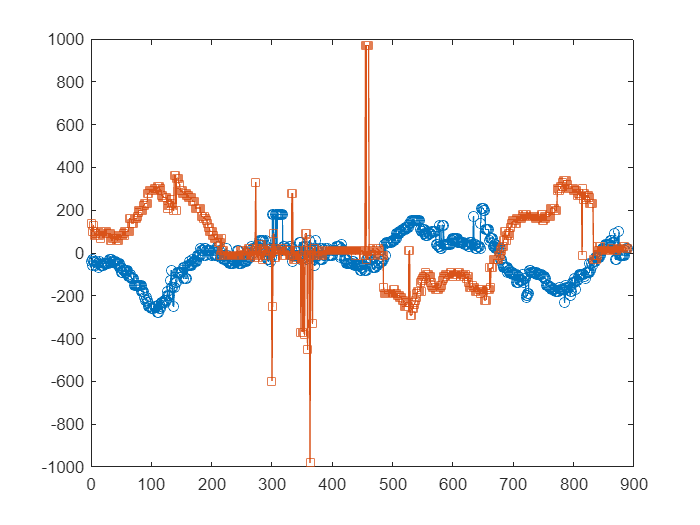


% 绘制两个数组到同一张图中
figure;
xValues = 1:max_iter;
plot(xValues, f1Array, 'o-', 'DisplayName', 'f1Array');
hold on;  % 保持图形，以便绘制下一个数组
plot(xValues, f2Array, 's-', 'DisplayName', 'f2Array');